## Task 1

Generate a rectangular signal A with 1000 samples and a period of 200 samples, with an amplitude of {-1, +1}. Add Gaussian noise with 0 mean and 0.1 sigma.

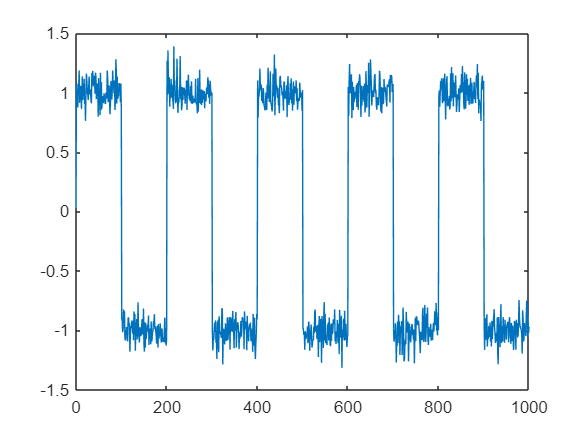

close all;
clear;
clc;

sample = (0:1000);
A = sign(sin(2*pi.*sample./200)); %Generates rectangular signal
noise = 0.1*randn(size(sample)); %Generate gaussian noise with mean 0 and std 0.1
a=A+noise; % Add the noise to the rectangular signal

figure(1),plot(sample,a);

## Task 2

Create three simple filters with a size of [1x3]:

F1=[1/3 1/3 1/3];
F2=[1/4 1/2 1/4];
F3=[-1 0 1];

Convolve input signal A with each of the filters.

f1=conv(a,F1);
f2=conv(a,F2);
f3=conv(a,F3);

Results from the convolution

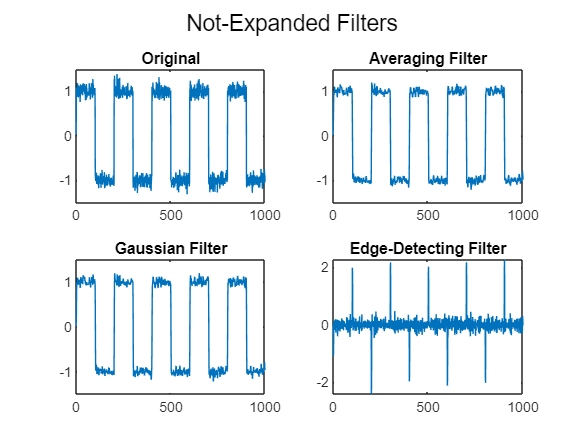

figure(2)
splot(2,2,1,a,'Original');
splot(2,2,2,f1,'Averaging Filter');
splot(2,2,3,f2,'Gaussian Filter');
splotx(2,2,4,f3,'Edge-Detecting Filter');
sgtitle('Not-Expanded Filters')

## Results and Goals of each type of filter

- Averaging Filter

Result from this convolution show an effect of eliminating noises from the signal values which are unrepresentative of their surroundings. It replaces signal values with average value of its neighbors.

- Gaussian Filter

The results are similar to mean filter, but in this case it replaces the values not with the mean but with the gaussian.

- Edge-Detecting Filter

The edge detecting filter simply detects where there is strong signs of change in the neighborhood.

#### Expand filters to a bigger size (5x1)

F4=[1/5 1/5 1/5 1/5 1/5];   
F5=[1/16 4/16 6/16 4/16 1/16]; 
F6=[-1 -1 0 1 1]; 

Convolve input signal A with Expanded filters.

f4=conv(a,F4);
f5=conv(a,F5);
f6=conv(a,F6);

Results from the convolution

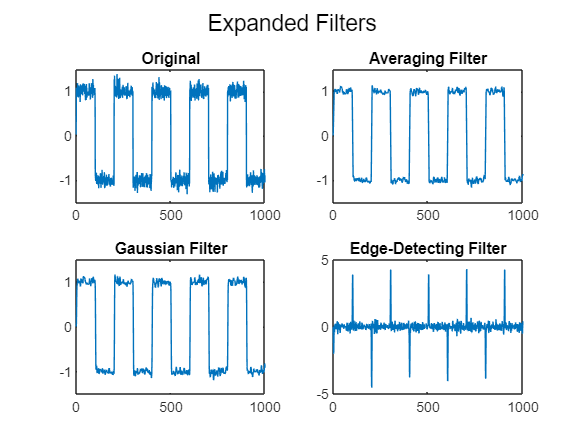

figure(3)
splot(2,2,1,a,'Original');
splot(2,2,2,f4,'Averaging Filter');
splot(2,2,3,f5,'Gaussian Filter');
splotx(2,2,4,f6,'Edge-Detecting Filter');
sgtitle('Expanded Filters') 

What happens if the filters are not normalized

**"Normalized values** allow the comparison of corresponding normalized values for different datasets in a way that eliminates the effects of certain gross influences. " [https://en.wikipedia.org/wiki/Normalization_(statistics)](https://en.wikipedia.org/wiki/Normalization_(statistics))

Thus normalizing the filter allows comparison of the different filters in our case we can compare the (3x1) and (5x1).

## Task 3

My convolution

Using the filters F1, F2, F3

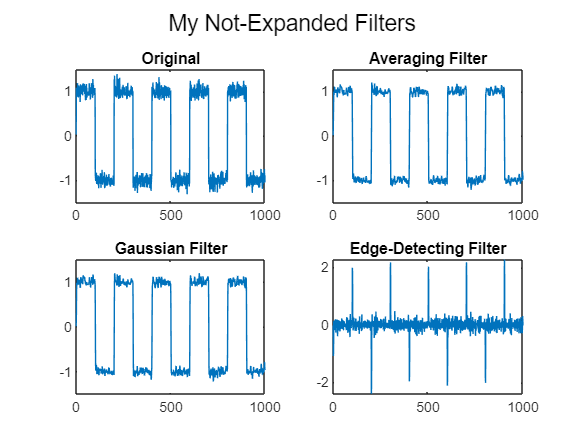

myf1=myconv(a,F1);
myf2=myconv(a,F2);
myf3=myconv(a,F3);

figure(4)
splot(2,2,1,a,'Original');
splot(2,2,2,myf1,'Averaging Filter');
splot(2,2,3,myf2,'Gaussian Filter');
splotx(2,2,4,myf3,'Edge-Detecting Filter');
sgtitle('My Not-Expanded Filters')

Using the expanded filters F4, F5 and F6

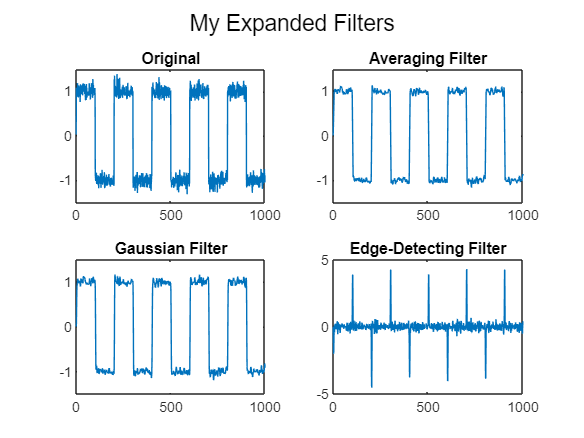

myf4=myconv(a,F4);
myf5=myconv(a,F5);
myf6=myconv(a,F6);

figure(5)
splot(2,2,1,a,'Original');
splot(2,2,2,myf4,'Averaging Filter');
splot(2,2,3,myf5,'Gaussian Filter');
splotx(2,2,4,myf6,'Edge-Detecting Filter');
sgtitle('My Expanded Filters')

Comparision of results of task 3 with the results of task 2

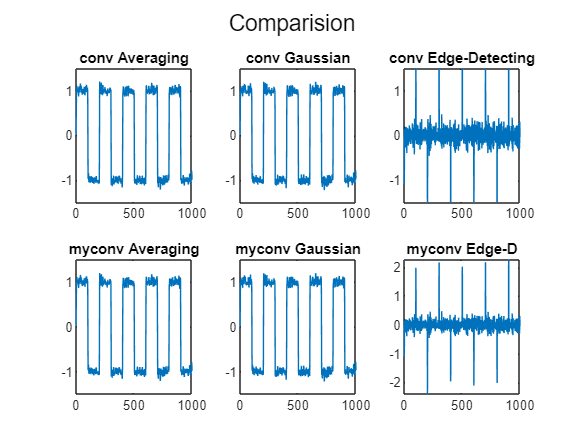

figure(6)
splot(2,3,1,f1,'conv Averaging');
splot(2,3,2,f2,'conv Gaussian');
splot(2,3,3,f3,'conv Edge-Detecting');
splot(2,3,4,myf1,'myconv Averaging');
splot(2,3,5,myf2,'myconv Gaussian');
splotx(2,3,6,myf3,'myconv Edge-D');
sgtitle('Comparision')

function splot(n,m,x,a,t)
subplot(n,m,x)
plot(a)
xlim([0 1000])
ylim([-1.5 1.5])
title(t)
end

function splotx(n,m,x,a,t)
subplot(n,m,x)
plot(a)
xlim([0 1000])
title(t)
end

function Y=myconv(x,h)
m=length(x);
n=length(h);
X=[x,zeros(1,n)];
H=[h,zeros(1,m)];

Y=zeros(size((n+m-1)));

for i=1:n+m-1
    Y(i)=0;
    for j=1:m
        if(i-j+1>0)
            Y(i)=Y(i)+H(j)*X(i-j+1);
        else
        end
    end
end

end